# Pruebas de filtro Fourier & Filtro Lanczos

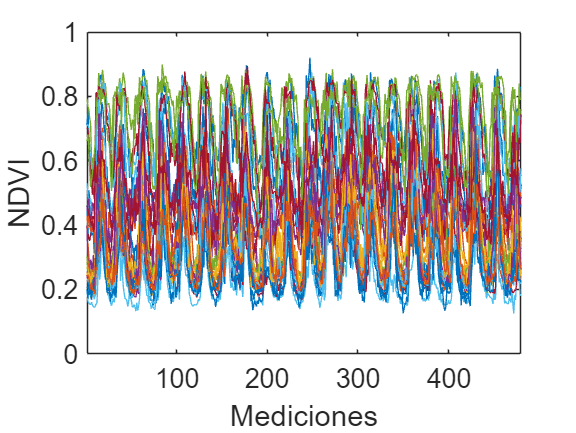

clear;
load tseries_test.mat;

figure;
plot(tseries_test');
xlabel('Mediciones')
ylabel('NDVI');
ylim([0 1]);
xlim([1 480]);
ax = gca;
ax.FontSize=16; 

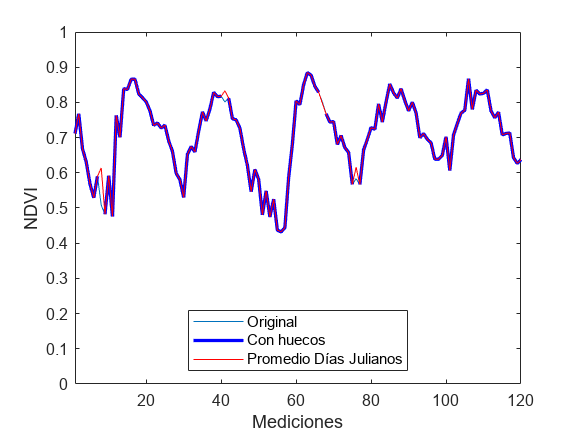

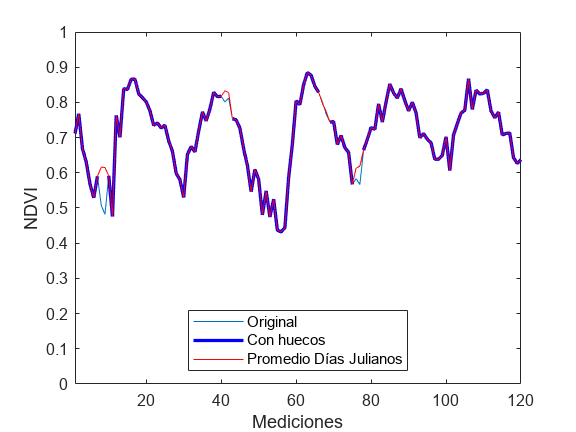

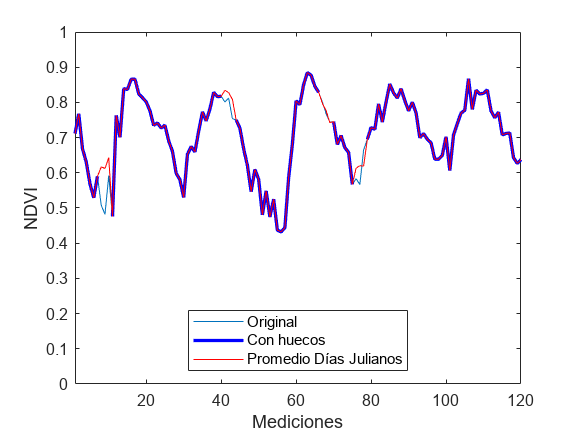

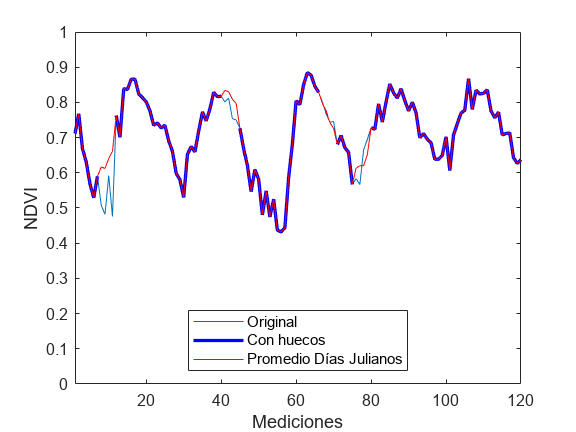

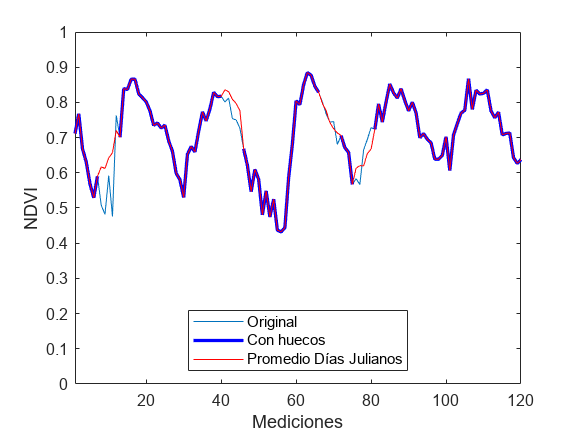

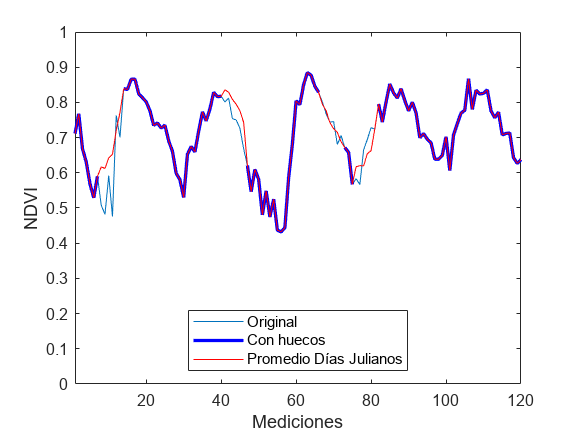

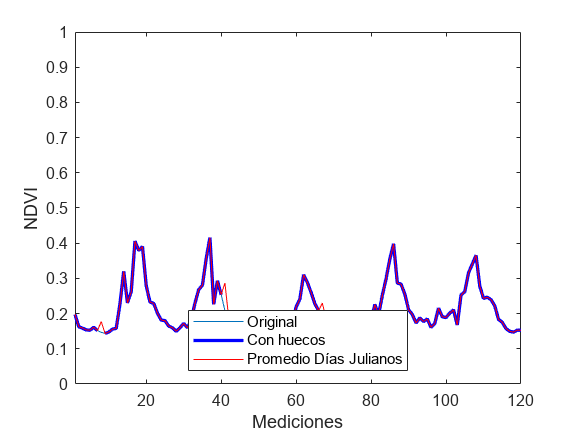

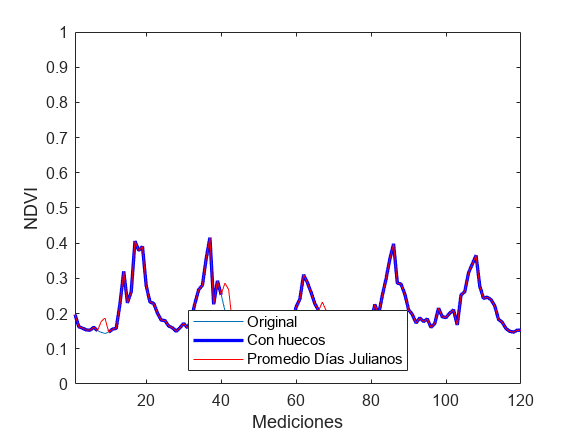



[numero_series,tam_serie] = size(tseries_test);
id = 29;
stat_f = zeros(30,24);
stat_l = zeros(30,24);
stat_s = zeros(30,24);

for id=1:30
    S = tseries_test(id,:);

    for nh=1:6
        [Sh,Snan] = artificial_holes(S,nh);
        Sh = f_fill_mean_julian(Snan,23);
         

        if any(id == [1 6 24])
            figure;
            plot(S);
            hold on
            plot(Snan,"b",LineWidth=2);
            plot(Sh,"r");
            hold off
            legend('Original','Con huecos','Promedio Días Julianos',Location='south');
            xlabel('Mediciones')
            ylabel('NDVI');
            ylim([0 1]);
            xlim([1 120]);
            exportgraphics(gca,"img/ac_huecos_120_"+id+"_"+nh+".png",'Resolution',300); 
        end

        
        Sl = lanczosfilter(Snan,23,0.02,[],'low');

        Sf = ffilter_mean(Sh,0,23);

        Ss = fillmissing(S,"linear");
        Ss = sgolayfilt(Ss,3,7);


        [a,b,c,d] = compare_serie_stat(S,Sf);
        pos = (nh*4)-3;
        stat_f(id,pos) = a;
        stat_f(id,pos+1) = b;
        stat_f(id,pos+2) = c;
        stat_f(id,pos+3) = d;
        
        [a,b,c,d] = compare_serie_stat(S,Sl');
        pos = (nh*4)-3;
        stat_l(id,pos) = a;
        stat_l(id,pos+1) = b;
        stat_l(id,pos+2) = c;
        stat_l(id,pos+3) = d;
        
        [a,b,c,d] = compare_serie_stat(S,Ss);
        pos = (nh*4)-3;
        stat_s(id,pos) = a;
        stat_s(id,pos+1) = b;
        stat_s(id,pos+2) = c;
        stat_s(id,pos+3) = d;
    end

end

disp("Estadisticos");

Estadisticos


disp(stat_f);

  Columns 1 through 7

   0.007415566164042   0.003017458356177   0.997357944574447   0.994711829584022   0.011310103321006   0.003690728156309   0.993848018276284
   0.012157866173046   0.002397370739675   0.995539056234779   0.991079389083999   0.015912599183328   0.003636987551196   0.992343955646099
   0.009522963581284   0.001392438807458   0.995503841394116   0.991009128143057   0.014993160662595   0.003376692473448   0.988829872948802
   0.017355681054599   0.002700601721509   0.990599738013132   0.981248694175435   0.022362561917204   0.004727353936999   0.984555332100621
   0.008285024641736   0.001473639292011   0.997085169696909   0.994166657461374   0.014078969738942   0.002399455211659   0.991550208163599
   0.008067767811286   0.001199982309942   0.992665625334030   0.985354468497456   0.011075728990320   0.002584564790404   0.986135195706869
   0.007013208497558   0.003441218564564   0.997119587502981   0.994235437204253   0.010269923240429   0.004642866442934   0.993811

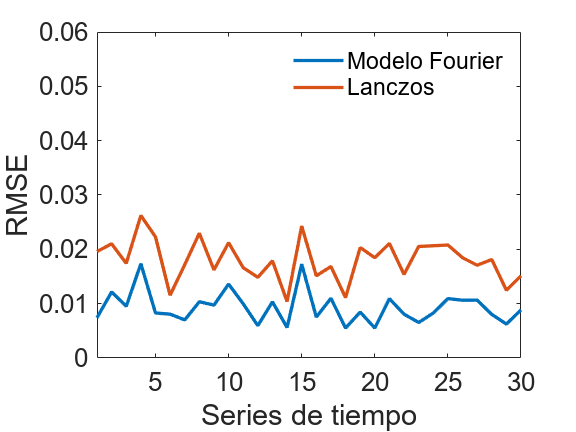

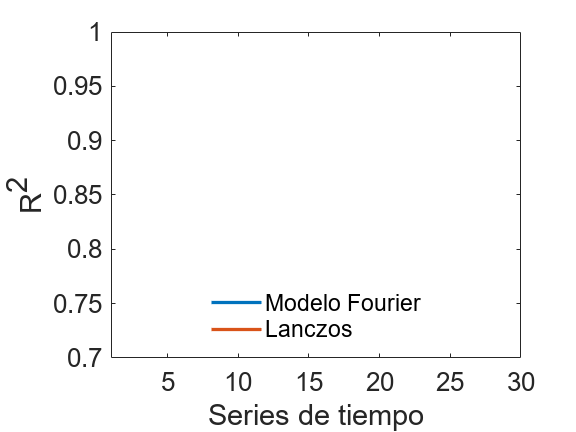

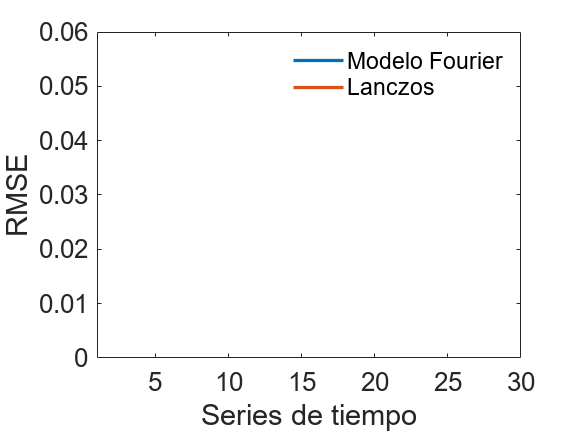

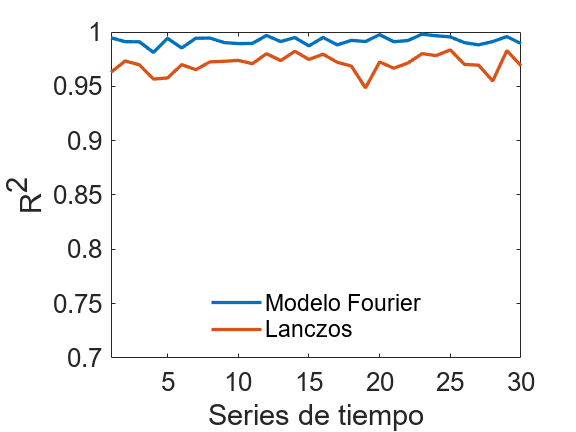

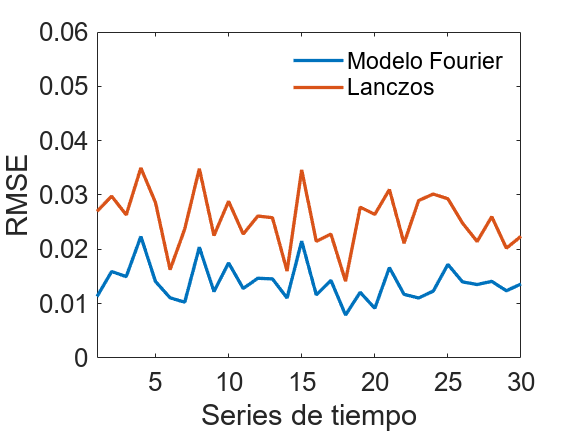

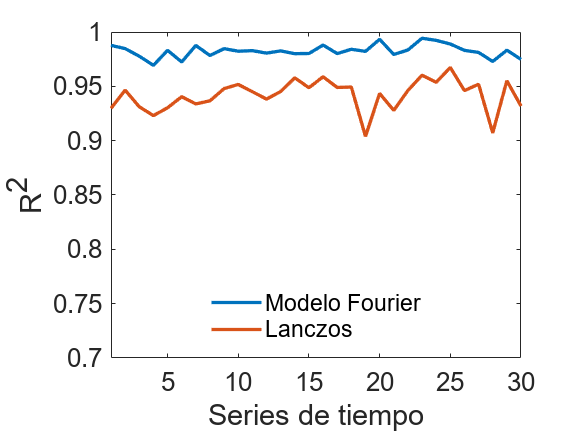

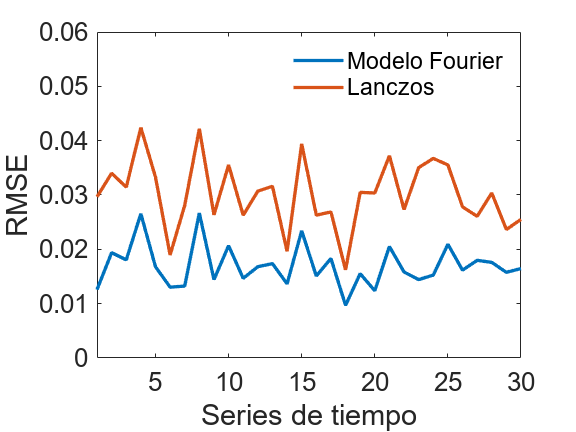

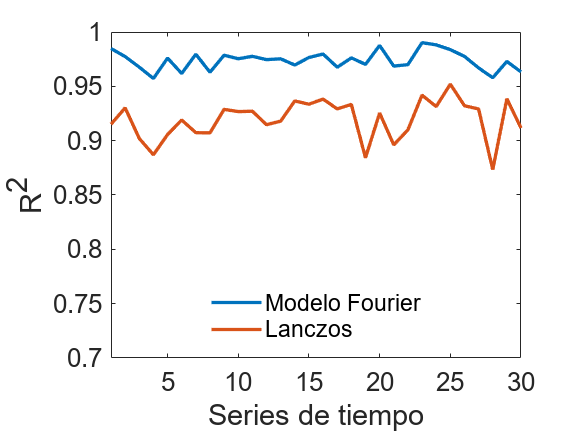

prom = mean(stat_f);

nh=1;
for nh=1:6
    pos = (nh*2)-1;
    %RMSE
    figure;
    plot(1:30,stat_f(:,pos),1:30,stat_l(:,pos),LineWidth=2);
    xlabel('Series de tiempo')
    ylabel('RMSE')
    xlim([1 30])
    ylim([0 0.06]);
    ax = gca;
    ax.FontSize=16; 
    legend('Modelo Fourier','Lanczos',Location='northeast');
    legend('boxoff');
    exportgraphics(gca,"img/RMSE_TSF_H"+nh+".png",'Resolution',300) 
    
    %CORR
    figure;
    plot(1:30,stat_f(:,pos+1),1:30,stat_l(:,pos+1),LineWidth=2);
    xlabel('Series de tiempo')
    ylabel('R^2')
    xlim([1 30])
    ylim([0.7 1]);
    ax = gca;
    ax.FontSize=16; 
    legend('Modelo Fourier','Lanczos',Location='south');
    legend('boxoff');
    exportgraphics(gca,"img/R2_TSF_H"+nh+".png",'Resolution',300) 
end

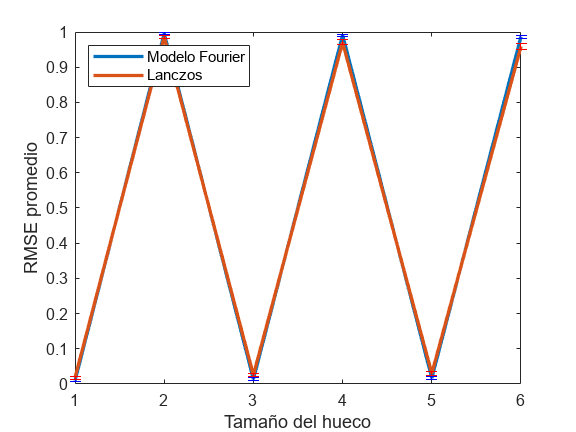

% Resumen
media_l =mean(stat_l);
media_f = mean(stat_f);
media_s =mean(stat_s);

std_l =std(stat_l);
std_f = std(stat_f);
std_s = std(stat_s);

%RMSE
figure;
p1=plot(1:6,media_f(1:2:12),1:6,media_l(1:2:12),LineWidth=2);
xlabel('Tamaño del hueco')
ylabel('RMSE promedio')
%xlim([1 30])
%ylim([0 0.05]);

hold on
er=errorbar(1:6,media_f(1:2:12),std_f(1:2:12)); 
er.Color = [0 0 1];                          
er.LineStyle = 'none';  
er=errorbar(1:6,media_l(1:2:12),std_l(1:2:12)); 
er.Color = [1 0 0];	                           
er.LineStyle = 'none'; 
% er=errorbar(1:6,media_s(1:2:12),std_s(1:2:12)); 
% er.Color = [1 1 0];	                           
% er.LineStyle = 'none'; 
hold off
%legend('Filtro fourier','Lanczos');
legend(p1,{'Modelo Fourier','Lanczos'},Location="northwest")

    exportgraphics(gca,"img/RMSE_TSF_mean.png",'Resolution',300) 

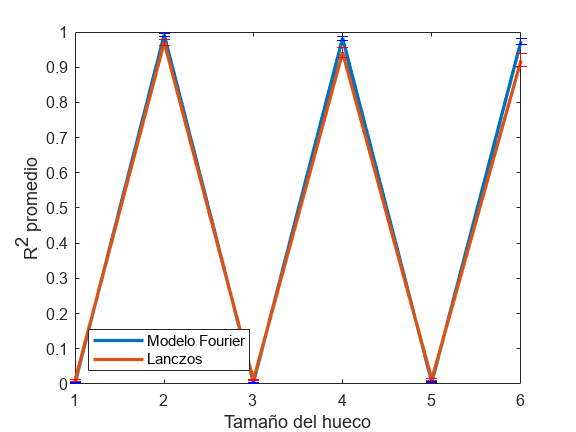


%CORR
figure;
p1=plot(1:6,media_f(2:2:12),1:6,media_l(2:2:12),LineWidth=2);
xlabel('Tamaño del hueco')
ylabel('R^2 promedio')
%xlim([1 30])
%ylim([0.9 1]);
hold on
er=errorbar(1:6,media_f(2:2:12),std_f(2:2:12)); 
er.Color = [0 0 1];                          
er.LineStyle = 'none';  
er=errorbar(1:6,media_l(2:2:12),std_l(2:2:12)); 
er.Color = [1 0 0];	                           
er.LineStyle = 'none'; 
% er=errorbar(1:6,media_s(2:2:12),std_s(2:2:12)); 
% er.Color = [1 1 0];	                           
% er.LineStyle = 'none'; 
hold off
legend(p1,{'Modelo Fourier','Lanczos'},Location="southwest")
    exportgraphics(gca,"img/R2_TSF_mean.png",'Resolution',300) 

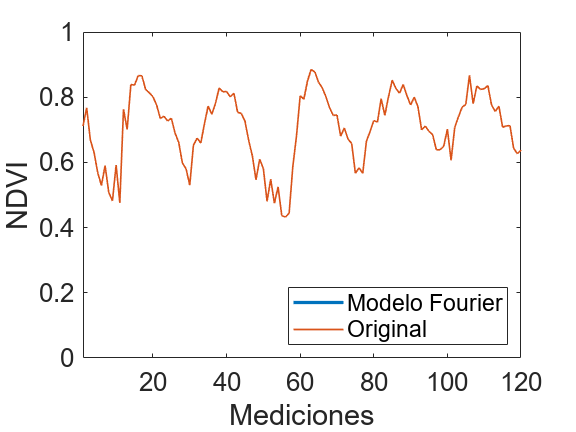

id=1;
    S = tseries_test(id,:);

    for nh=1:6
        [Sh,Snan] = artificial_holes(S,nh);

        

        Sf = ffilter_mean(Sh,0,23);

        figure;
        plot(Sf, LineWidth=2);
        
        hold on
        % plot(Sl,"r");
        % plot(Ss,"y");
        plot(1:tam_serie,S, LineWidth=1);%,1:tam_serie,Snan);
        hold off
        legend('Modelo Fourier','Original',Location='southeast');
        xlabel('Mediciones')
        ylabel('NDVI');
        ylim([0 1]);
        xlim([1 120]);
        ax = gca;
        ax.FontSize=16; 
        %figure;
        % yyaxis left;
        % plot(1:30,stat_f(:,1));
        % xlabel('Rng')
        % ylabel('RMSE')
        % xlim([1 30])
        % 
        % yyaxis right;
        % plot(1:30,stat_f(:,2));
        % ylabel('R2')
            exportgraphics(gca,"img/completar"+nh+".png",'Resolution',300) 

    end 

function [Sh,Snan] = artificial_holes(S,tam_huecos)
    id_huecos= [7 40 66 75 120 197 263 291 341 401 438];
    Snan=S;
    for i=id_huecos
        for j=1:tam_huecos
            Snan(i+j)=nan;
        end
    end
     Sh = Snan;
%     for i=id_huecos
%         for j=1:tam_huecos
%             idp = (i+j):23: length(S);
%             prom = mean(Sh(idp),"all","omitnan");
%             Sh(i+j) = prom;
%         end
%     end
end

% % function [Smean] = fill_mean_julian(Snan)
% %     tam = length(Snan);
% %     Smean = Snan;
% %     for i=1:tam
% %         if(isnan(Snan(i)))
% %             idp = i:23:tam;
% %             prom = mean(Snan(idp),"all","omitnan");
% %             Smean(i) = prom;
% %         end
% %     end
% % end


function [Sf,Yf,f,P1] = ffilter_mean(Sh,rng,Fs)
    L = length(Sh);      % Length of signal
    mit = L/2;

    Yf = fft(Sh);
    Yf(mit-rng+1:mit+rng+1) = 0;

    Yfp = abs(Yf);
    P2 = abs(Yfp/L);
    P1 = P2(1:int16(L/2)+1);
    P1(2:end-1) = 2*P1(2:end-1);
    f = Fs*(0:(L/2))/L;
    Sf = real(ifft(Yf));
end

function [m_rmse,m_mae,m_corr,m_r2] = compare_serie_stat(S,Sl)
    m_rmse = f_rmse(S,Sl);
    m_mae = f_mae(S,Sl);
    cor = corrcoef(S,Sl);
    m_corr = cor(2,1);
    % m_sesgo_s = skewness(S)
    % m_sesgo_sf =skewness(Sl)
    mdl = fitlm(S,Sl);
    %m_R2o = mdl.Rsquared.Ordinary;
    m_r2 = mdl.Rsquared.Adjusted;
end